## 0. Parámetros Físicos

L = 20;              % Distancia de fibra en km (Ej. 25km, 50km)
alpha = 0.2;         % Atenuación de la fibra estándar (dB/km)
Va = 4;              % Varianza de modulación de Alice (VA). Típico: 4-20 SNU.
T = 10^(-alpha * L / 10) %Transmitancia

T = 0.3981

% Parámetros de Ruido
vel = 0.05;          % Ruido electrónico del detector (0.05 = 5% del shot noise)
xi = 0.01;           % Ruido de exceso a la entrada (Excess Noise). Típico: 0.01
% Tamaños
n = 26112

n = 26112

max_iter = 60

max_iter = 60

N_pulsos = 100000 %Número de pulsos que vamos a generar (tiene que ser mayor para generar varias veces)

N_pulsos = 100000

## 1. Generación (Alice)

%Generamos los números Aleatorios de Alice
q_Alice = sqrt(Va)*randn(N_pulsos, 1)

q_Alice =     0.3413
   -0.9327
   -1.4781
   -2.1117
    4.0389
    3.0452
    0.8645
    0.9916
    0.8092
   -1.0575
    1.5604
   -6.5080
   -1.6466
   -1.5416
    2.1041


p_Alice = sqrt(Va)*randn(N_pulsos, 1)

p_Alice =    -0.1962
   -0.4566
    3.4739
   -0.0662
   -1.9280
   -3.9921
    2.8204
   -1.3269
    4.7221
   -0.4884
    0.2366
    2.9805
    0.8939
    0.8639
    0.7437


Xa = zeros(2 * N_pulsos, 1)

Xa =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% Intercalado (Interleaving)
Xa(1:2:end) = q_Alice; % Posiciones impares: Q
Xa(2:2:end) = p_Alice; % Posiciones pares: P

%Simulación de Ruido
%variables de ruido
var_noise = 1 + vel + T * xi %varianza del ruido

var_noise = 1.0540

std_noise = sqrt(var_noise) %desviación típica del ruido

std_noise = 1.0266

% ruido como tal
z_noise_p = std_noise * randn(N_pulsos, 1)

z_noise_p =    -0.8784
   -0.1154
   -0.1203
    0.8184
   -1.1158
   -0.2506
    0.5277
   -0.8100
    2.1582
    2.7181
   -1.0394
    0.5418
   -0.1403
    0.0671
   -0.0664


z_noise_q = std_noise * randn(N_pulsos, 1)

z_noise_q =    -0.5017
   -0.5385
    1.5587
   -0.0388
    0.3351
   -1.1647
    0.0584
   -0.0139
   -1.3031
    0.3058
   -0.8882
    1.0001
   -0.1324
    0.0978
   -0.8672


## 2. Recepción (Bob)

p_Bob = sqrt(T) * p_Alice + z_noise_p

p_Bob =    -1.0023
   -0.4034
    2.0716
    0.7766
   -2.3323
   -2.7695
    2.3072
   -1.6473
    5.1377
    2.4099
   -0.8901
    2.4224
    0.4237
    0.6122
    0.4028


q_Bob = sqrt(T) * q_Alice + z_noise_q

q_Bob =    -0.2863
   -1.1270
    0.6260
   -1.3712
    2.8835
    0.7567
    0.6039
    0.6117
   -0.7926
   -0.3615
    0.0963
   -3.1062
   -1.1714
   -0.8748
    0.4604


Yb = zeros(2*N_pulsos,1)

Yb =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Yb(1:2:end) = q_Bob; % Posiciones impares: Q
Yb(2:2:end) = p_Bob; % Posiciones pares: P

## 2.1 Representación de Valores y cálculo parámetros interesantes

%Todo esto es muy extra de chati
% Potencia de señal recibida / Potencia de ruido total
Signal_Power_Rx = T * Va;
Noise_Power_Rx  = var_noise;

SNR_lineal = Signal_Power_Rx / Noise_Power_Rx;
SNR_dB = 10 * log10(SNR_lineal)

SNR_dB = 1.7923

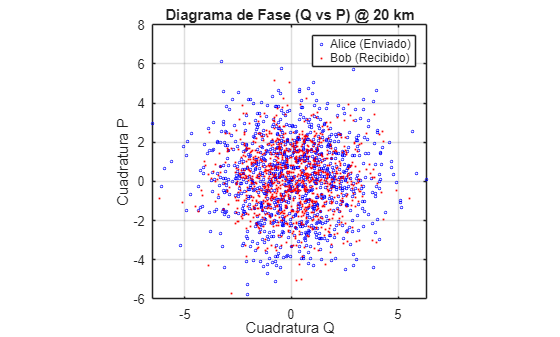


figure;
% Mostramos solo los primeros 1000 puntos para no saturar la gráfica
plot(q_Alice(1:1000), p_Alice(1:1000), 'bo', 'MarkerSize', 2); hold on;
plot(q_Bob(1:1000), p_Bob(1:1000), 'r.', 'MarkerSize', 4);
legend('Alice (Enviado)', 'Bob (Recibido)');
title(['Diagrama de Fase (Q vs P) @ ' num2str(L) ' km']);
xlabel('Cuadratura Q'); ylabel('Cuadratura P');
axis square; grid on;

## 3. Generación de H

%% 3. GENERACIÓN DE MATRIZ H (LDPC 5G NR)
% -------------------------------------------------------------------------
% Cargar Base Graph 1 del estándar 5G NR-LDPC
Z = 384;                            % Factor de lifting
baseGraphFile = 'C:\Users\usser\OneDrive - Universidad Politécnica de Madrid\INDUSTRIALES I DANI\GRADO\TFG\LDPC\NR-LDPC-BG-master\NR-LDPC-BG-master\NR_1_1_384.txt';

% Leer la matriz base desde archivo
BaseGraph = load(baseGraphFile);
[mb, nb] = size(BaseGraph);         % BG1: 46×68

% Dimensiones finales de H
M = mb * Z;                         % 17,664 filas (ecuaciones de paridad)
N_ldpc = nb * Z;                    % 26,112 columnas (bits totales)

fprintf('Matriz Base: %d×%d, Z=%d → H: %d×%d\n', mb, nb, Z, M, N_ldpc);

Matriz Base: 46×68, Z=384 → H: 17664×26112



% Expansión de la matriz (lifting) usando matrices sparse
% Pre-calcular número de elementos no nulos para eficiencia
num_nonzero_blocks = sum(BaseGraph(:) >= 0);
nnz_total = num_nonzero_blocks * Z;

% Pre-asignar arrays para construcción sparse eficiente
row_indices = zeros(nnz_total, 1);
col_indices = zeros(nnz_total, 1);
values = ones(nnz_total, 1);

idx = 1;
for i = 1:mb
    for j = 1:nb
        shift_val = BaseGraph(i, j);
        if shift_val >= 0
            % Índices de la submatriz identidad rotada
            row_base = (i-1) * Z;
            col_base = (j-1) * Z;
            
            % Generar índices de la identidad circulante
            for k = 1:Z
                row_indices(idx) = row_base + k;
                col_indices(idx) = col_base + mod(k - 1 + shift_val, Z) + 1;
                idx = idx + 1;
            end
        end
    end
end

% Construir matriz sparse
H = sparse(row_indices, col_indices, values, M, N_ldpc)

H = 17664×26112 sparse double matrix (121344 nonzeros)
        (78,1)              1
       (693,1)              1
       (948,1)              1
      (1261,1)              1
      (1589,1)              1
      (2110,1)              1
      (2411,1)              1
      (3064,1)              1
      (3150,1)              1
      (3475,1)              1
      (4561,1)              1
      (4916,1)              1
      (5064,1)              1
      (5619,1)              1
      (5904,1)              1
      (6653,1)              1
      (7536,1)              1
      (7878,1)              1
      (8803,1)              1
      (9303,1)              1
     (10298,1)              1
     (10915,1)              1
     (11746,1)              1
     (12571,1)              1
     (13211,1)              1
     (13999,1)              1
     (14792,1)              1
     (15570,1)              1
     (16400,1)              1
     (17201,1)              1
        (79,2)              1
       (694,2) 


fprintf('Matriz H generada: %d elementos no nulos (densidad: %.4f%%)\n', nnz(H), 100*nnz(H)/(M*N_ldpc));

Matriz H generada: 121344 elementos no nulos (densidad: 0.0263%)


## 4. Estimación de parámetros

%Generamos los distintos vectores que necesitamos
Xr = Xa(1:2:2*n) %Los valores de X que vamos a usar para la reconciliación

Xr =     0.8567
   -0.6133
    4.0810
    2.5154
   -0.9125
   -3.0478
   -1.0740
   -0.0706
   -0.7517
   -6.0304
    0.9165
    1.3915
    3.8782
   -3.8443
   -0.5995


Xp = Xa(2:2:2*n) %Los valores de X que vamos a usar para la estimación de parámetros

Xp =     1.0863
    0.8865
    2.0239
   -1.3083
    0.9038
    0.0132
    1.5820
   -0.8228
   -1.0594
   -0.1541
   -0.2441
   -2.7284
   -4.7490
    3.5599
   -0.5661


Yr = Yb(1:2:2*n) %Los valores de Y que vamos a usar para la reconciliación

Yr =     0.0128
   -0.8733
    2.3989
    0.3688
    1.8174
   -1.4009
    0.0721
   -0.0160
   -2.9785
   -3.6847
    1.7613
    0.3425
    2.9128
   -2.4274
   -0.6654


Yp = Yb(2:2:2*n) %Los valores de Y que vamos a usar para la estimación de parámetros

Yp =    -0.1645
   -0.2672
    0.1972
    0.3884
    0.7221
    0.8896
    0.8854
   -0.6823
    0.6345
   -1.5820
   -1.8273
   -1.9610
   -3.3671
    1.4013
    0.3292


%Estimamos T
Cov_xy = cov(Xp, Yp) %matriz de covarianzas

Cov_xy =     4.0065    2.5203
    2.5203    2.6203


covarianza_xy = Cov_xy(1, 2) 

covarianza_xy = 2.5203

varianza_x = var(Xp)

varianza_x = 4.0065

T_estimada = (covarianza_xy / varianza_x)^2

T_estimada = 0.3957


%Estimación del ruido residual
sigma2 = var(Yp - sqrt(T_estimada)*Xp)

sigma2 = 1.0349

z_est = (sigma2 - 1 - vel)/T_estimada

z_est = -0.0382

## 5. Cálculo del Síndrome

%Calculamos el síndrome
Kb = zeros(n, 1)

Kb =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Kb(Yr <= 0) = 1; 
Kb(Yr > 0)  = 0;
S = mod(H * Kb, 2)

S =      0
     0
     0
     0
     1
     0
     1
     0
     1
     0
     1
     0
     0
     1
     0


## 6. Reconciliación Inversa

### 6.0

alpha_minsum = 0.75;    % Factor de escala del Min-Sum (distinto de alpha_atenuacion)
debug_mode   = true;    % Muestra progreso por iteración

### 6.1. Inicialización

[rows, cols] = find(H);        % vectores columna de longitud num_edges
num_edges    = length(rows);

### 6.2. Busqueda de los valores mínimos de cada Check-Node

LLR = (2 * sqrt(T_estimada) / sigma2) .* Yr;   % (N×1)

### 6.3 Cálculo de los valores de cada elemento de R

% Mensajes variable→check inicializados al LLR del canal
L_edges = LLR(cols);        % (num_edges×1)  L_{n→m} para cada arista

% Mensajes check→variable (se calculan en el loop)
R_edges = zeros(num_edges, 1);

% Ajuste de síndrome: si S(m)=1, el check-node m invierte su signo global.
% Representamos esto como ±1 multiplicado sobre los mensajes de salida.
syndrome_sign = (-1).^S;    % (M×1)

### 6.4. Cálculo del signo de cada elemento

success = false;

for iter = 1:max_iter

    % ── PASO A: Actualización de Check-Nodes (check → variable) ──────────
    %
    % Para cada check-node m y cada arista e saliente hacia variable-node n:
    %   R_{m→n} = síndrome_sign(m) · sign(∏_{n'≠n} L_{n'→m}) · min_{n'≠n}|L_{n'→m}|
    %
    % Implementación vectorizada con índice de fila (rows):

    % A.1 — Signo acumulado por check-node (producto de todos los signos entrantes)
    signs_L   = sign(L_edges);
    signs_L(signs_L == 0) = 1;                          % evitamos signo cero

    % Paridad total por check-node: producto de todos los signos
    row_sign_product = accumarray(rows, double(signs_L < 0), [M, 1]);
    % (cuenta cuántos negativos hay; impar → producto negativo)
    global_sign = syndrome_sign .* ((-1).^row_sign_product);   % (M×1)

    % A.2 — Magnitud mínima y segunda mínima por check-node
    abs_L = abs(L_edges);

    % Ordenamos aristas por (fila, magnitud) para encontrar min1 y min2
    [sorted_abs, sort_idx]  = sortrows([rows, abs_L], [1, 2]);
    sorted_rows             = sorted_abs(:, 1);
    sorted_abs_vals         = sorted_abs(:, 2);
    sorted_cols_orig        = cols(sort_idx);            % VN original de cada arista

    [unique_rows, first_idx] = unique(sorted_rows, 'first');

    % min1 y min2 para cada check-node (filas de H)
    min1_val = inf(M, 1);
    min1_col = zeros(M, 1);
    min2_val = inf(M, 1);

    min1_val(unique_rows) = sorted_abs_vals(first_idx);
    min1_col(unique_rows) = sorted_cols_orig(first_idx);

    % min2: primer elemento que NO sea el mismo que min1
    for k = 1:length(unique_rows)
        m   = unique_rows(k);
        idx = first_idx(k) + 1;
        if idx <= num_edges && sorted_rows(idx) == m
            min2_val(m) = sorted_abs_vals(idx);
        end
    end

    % A.3 — Magnitud del mensaje R para cada arista
    %   Si la arista e ES la que tenía el mínimo en su fila → usamos min2
    %   Si NO es la mínima → usamos min1
    is_min_edge       = (cols == min1_col(rows));        % máscara lógica (num_edges×1)
    R_mags            = zeros(num_edges, 1);
    R_mags(~is_min_edge) = min1_val(rows(~is_min_edge));
    R_mags( is_min_edge) = min2_val(rows( is_min_edge));
    R_mags = alpha_minsum * R_mags;                      % escala Min-Sum

    % A.4 — Signo extrínseco: signo global del check-node × signo de la arista entrante
    %   El mensaje saliente excluye el signo de la arista propia → lo dividimos
    R_signs = global_sign(rows) .* signs_L;             % extrínseco = total / self
    R_edges = R_signs .* R_mags;

    % ── PASO B: Actualización de Variable-Nodes (variable → check) ───────
    %
    % L_{n→m} = LLR(n)  +  Σ_{m'≠m} R_{m'→n}
    %         = LLR(n)  +  (suma total de R entrantes a n)  −  R_{m→n}

    R_sum_per_VN = accumarray(cols, R_edges, [N, 1]);    % suma total por VN
    L_edges      = LLR(cols) + R_sum_per_VN(cols) - R_edges;   % extrínseco

    % ── PASO C: Decisión Hard ────────────────────────────────────────────
    LLR_total = LLR + R_sum_per_VN;                     % LLR aposteriori (N×1)
    Ka_hat    = double(LLR_total < 0);                  % bit estimado de Alice

    % ── PASO D: Criterio de Parada (comprobación de paridad) ─────────────
    S_check = mod(H * Ka_hat, 2);
    if isequal(S_check, S)
        success = true;
        if debug_mode
            fprintf('✔ Decodificación correcta en iteración %d\n', iter);
        end
        break;
    end

    if debug_mode && mod(iter, 10) == 0
        ber_partial = mean(Ka_hat ~= double(Yr <= 0));
        fprintf('  iter %3d  |  BER parcial = %.5f\n', iter, ber_partial);
    end

end

✔ Decodificación correcta en iteración 1



if ~success
    fprintf('✘ No convergió en %d iteraciones.\n', max_iter);
end

### 6.5

% BER final entre la estimación de Alice y los bits de Bob
Kb_ref  = double(Yr <= 0);                              % bits de Bob (referencia)
BER     = mean(Ka_hat ~= Kb_ref);
fprintf('BER final            = %.6f\n', BER);

BER final            = 0.000000



% Tasa de código y eficiencia de reconciliación β
code_rate   = (N - M) / N;
I_AB        = 0.5 * log2(1 + T_estimada * Va / sigma2); % info mutua GG02 (bits/uso)
beta        = code_rate / I_AB;
fprintf('Tasa de código       = %.4f\n', code_rate);

Tasa de código       = 0.3235


fprintf('Información mutua    = %.4f bits/uso\n', I_AB);

Información mutua    = 0.6694 bits/uso


fprintf('Eficiencia β         = %.4f  (objetivo > 0.95)\n', beta);

Eficiencia β         = 0.4833  (objetivo > 0.95)



% Tasa de clave secreta (simplificada, sin privacidad amplificada)
% K_secret ≈ beta * I_AB - chi_BE  (chi_BE requiere análisis de seguridad adicional)
fprintf('\nNota: para la tasa de clave secreta completa, resta el\n');


Nota: para la tasa de clave secreta completa, resta el


fprintf('      parámetro de Holevo chi_BE (requiere análisis de seguridad).\n');

      parámetro de Holevo chi_BE (requiere análisis de seguridad).
